%% ============================================================
% TASK 5 - TESTING THE SINGLE-PHOTON SCANNING CAMERA
%
% Illuminated star map
%        ↓
%   Lens / telescope
%        ↓
% Beam-steering mirror
%        ↓
% Single-mode fibre
%        ↓
%    SPCM-AQRH
%
% The beam-steering mirror scans the image across the
% single-mode fibre.
%
% ============================================================

clear;
clc;
close all;


%% ============================================================
% 1. CREATE ILLUMINATED STAR MAP
% ============================================================

MAP_WIDTH  = 100;
MAP_HEIGHT = 100;

% Empty star map

starMap = zeros(MAP_HEIGHT, MAP_WIDTH);


% Define illuminated objects
%
% [X position, Y position, brightness]

stars = [
    20, 30, 100;
    45, 35, 200;
    70, 50, 150;
    80, 75, 250;
    35, 80, 180;
    60, 90, 120
];


% Place stars into the star map

for k = 1:size(stars,1)

    x = stars(k,1);
    y = stars(k,2);
    brightness = stars(k,3);

    starMap(y,x) = brightness;

end


%% ============================================================
% 2. DEFINE SPC FIELD OF VIEW
% ============================================================

% Telescope effective focal length

focalLength = 6459;       % mm


% Fibre / effective sampling diameter

fibreSize = 4.2e-3;       % mm
                          % 4.2 micrometres


% Calculate angular sampling size

SPC_FOV_arcsec = ...
    (fibreSize / focalLength) * 206265;


fprintf('SPC angular sampling size = %.4f arcsec\n', ...
    SPC_FOV_arcsec);

SPC angular sampling size = 0.1341 arcsec


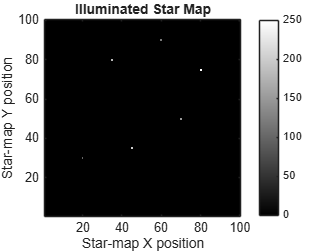



% ------------------------------------------------------------
% STAR-MAP PIXEL SCALE
% ------------------------------------------------------------
%
% For this first model we assume that one star-map pixel
% represents one 4.2 um sampling interval at the telescope
% focal plane.
%
% Therefore:
%
%       1 star-map pixel = 0.1341 arcsec
%
% ------------------------------------------------------------

STAR_PIXEL_SIZE_arcsec = SPC_FOV_arcsec;


% The fibre therefore covers approximately one 
% star-map pixel in this simplified model.

FOV_SIZE = 1;

radius = floor(FOV_SIZE / 2);


% Create circular FOV

[xFOV, yFOV] = meshgrid(-radius:radius, ...
                        -radius:radius);

FOV = (xFOV.^2 + yFOV.^2 <= radius^2);


%% ============================================================
% 3. BEAM-STEERING MIRROR SCAN
% ============================================================

% The mirror moves the optical image across the fibre.
%
% For now, scan positions are represented by star-map
% coordinates.
%
% Later these can be replaced by actual MR-E-3 mirror angles.

scanX = 1:MAP_WIDTH;
scanY = 1:MAP_HEIGHT;


%% ============================================================
% 4. CREATE OUTPUT IMAGE
% ============================================================

SPC_frame = zeros(MAP_HEIGHT, MAP_WIDTH);


%% ============================================================
% 5. SCAN THE STAR MAP
% ============================================================

for iy = 1:length(scanY)

    for ix = 1:length(scanX)

        % Current mirror position

        mirrorX = scanX(ix);
        mirrorY = scanY(iy);


        % ----------------------------------------------------
        % Determine FOV boundaries
        % ----------------------------------------------------

        xmin = mirrorX - radius;
        xmax = mirrorX + radius;

        ymin = mirrorY - radius;
        ymax = mirrorY + radius;


        % ----------------------------------------------------
        % Check that FOV remains inside star map
        % ----------------------------------------------------

        if xmin < 1 || xmax > MAP_WIDTH || ...
           ymin < 1 || ymax > MAP_HEIGHT

            continue;

        end


        % ----------------------------------------------------
        % Extract region currently observed by fibre
        % ----------------------------------------------------

        localScene = ...
            starMap(ymin:ymax, xmin:xmax);


        % ----------------------------------------------------
        % Calculate light entering fibre
        % ----------------------------------------------------

        fibreLight = ...
            sum(localScene(FOV), 'all');


        % ----------------------------------------------------
        % Store measurement
        % ----------------------------------------------------

        SPC_frame(iy,ix) = fibreLight;

    end

end


%% ============================================================
% 6. DISPLAY ILLUMINATED STAR MAP
% ============================================================

figure;

imagesc(starMap);

axis image;
set(gca,'YDir','normal');

colormap(gray);
colorbar;

xlabel('Star-map X position');
ylabel('Star-map Y position');

title('Illuminated Star Map');

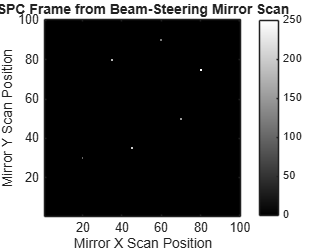




%% ============================================================
% 7. DISPLAY SCANNED SPC FRAME
% ============================================================

figure;

imagesc(SPC_frame);

axis image;
set(gca,'YDir','normal');

colormap(gray);
colorbar;

xlabel('Mirror X Scan Position');
ylabel('Mirror Y Scan Position');

title('SPC Frame from Beam-Steering Mirror Scan');



%% ============================================================
% 8. DISPLAY BASIC INFORMATION
% ============================================================

fprintf('\n');
fprintf('============================================\n');

fprintf('TASK 5 - SINGLE-PHOTON SCANNING CAMERA\n');

TASK 5 - SINGLE-PHOTON SCANNING CAMERA


fprintf('============================================\n');


fprintf('Telescope focal length: %.0f mm\n', ...
    focalLength);

Telescope focal length: 6459 mm



fprintf('Fibre diameter: %.1f micrometres\n', ...
    fibreSize * 1000);

Fibre diameter: 4.2 micrometres



fprintf('SPC angular sampling size: %.4f arcsec\n', ...
    SPC_FOV_arcsec);

SPC angular sampling size: 0.1341 arcsec



fprintf('Star-map pixel scale: %.4f arcsec/pixel\n', ...
    STAR_PIXEL_SIZE_arcsec);

Star-map pixel scale: 0.1341 arcsec/pixel



fprintf('Star map size: %d x %d pixels\n', ...
    MAP_WIDTH, MAP_HEIGHT);

Star map size: 100 x 100 pixels



fprintf('Mirror scan positions: %d x %d\n', ...
    length(scanX), length(scanY));

Mirror scan positions: 100 x 100



fprintf('============================================\n');